# Task 4: Dynamic SSE of CPSs under adversarial attacks

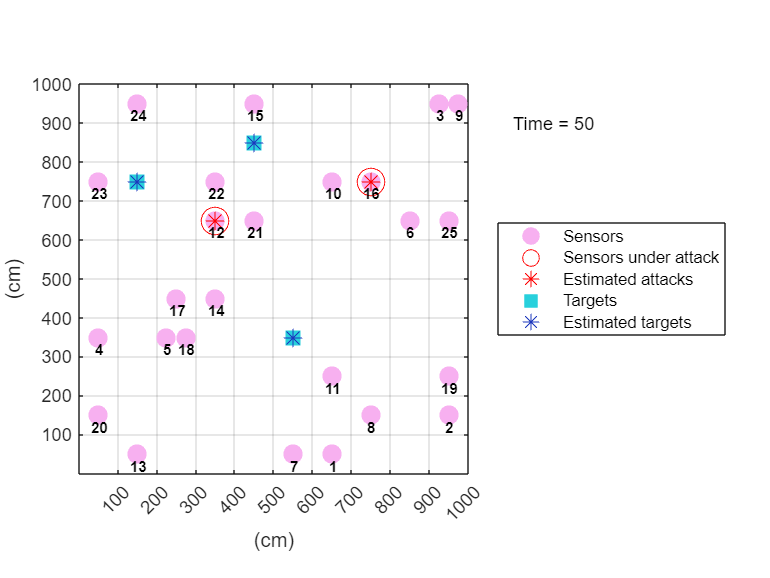

%-----------------------------------------------------
%  Project "Modeling and Control of CPS"
%           TASK 4 - Sparse observer
%                               
%                       Latest update: 21.04.2024
%                                
%-----------------------------------------------------
clear
close all
clc 

load tracking_moving_targets.mat    %load A,D,Y

p=100;          %number of the cells
q=25;           %number of sensors
Ntarget=3;
Nattack=2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                         OPTION START                                  %%  
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 0=unaware attack  1=aware attack
aware=0; 

%To use the change_sensor option the aware must bet set to 1

% 0=the sensors under attack are always the same for 50 time istants
% 1=the sensors under attack change every 25 seconds
change_sensors=0; 

if change_sensors==1 && aware==0
    return
end

Tmax=50; %It must be a multiple of 25 and the aware option must be set to 1

if mod(Tmax,25)~=0
    return
elseif ~aware && Tmax~=50
    return
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                         OPTION END                                    %%  
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

lammba1=10; lambda2=20; 
lambda=[10*ones(p,1); 20*ones(q,1)];
eps=1e-8; 
G = [D eye(q)];                 %augmented sensing matrix
G=normalize(G);
tau= (norm(G)^(-2))-eps;                    %step size


%z_hat = [xtrue; zeros(q,1)];       %stato iniziale 

mes_x = zeros(p,1); 
mes_a = zeros(q,1); 
z_hat = [zeros(p,1); zeros(q,1)];       %Initial state observer

xtrue=zeros(p,1);
atrue=zeros(q,1);
if aware
    
    %generate inital condition
    support_x_true = randperm(p);
    support_x_true = support_x_true(1:Ntarget); % I consider 3 targets
    xtrue(support_x_true) = 1;

    %generate attack support
    tmp_supp_a = randperm(q);
    tmp_supp_a = tmp_supp_a(1:Nattack); % I consider 2 sensors under attack
    %atrue(support_a_true) = 0; %->da eliminare
    sigma=1e-2; 
    noise = sigma*randn(q, 1);
    
    if change_sensors
        rep=Tmax/25;
        support_a_true=zeros(rep,Nattack);
        for i=1:rep        
            for j=((i-1)*25)+1:25*i
                Y(:,j) = D*xtrue + atrue + noise;
                atrue(tmp_supp_a)=0.5*Y(tmp_supp_a,j);
                xtrue=A*xtrue;
                %sup_a=[sup_a atrue];
            end
            %generate a new attack support
            atrue=zeros(q,1);
            support_a_true(i,:)=tmp_supp_a;
            tmp_supp_a = randperm(q);
            tmp_supp_a = tmp_supp_a(1:Nattack); % I consider 2 sensors under attack
            
        end
    else
        for i=1:Tmax
            Y(:,i) = D*xtrue + atrue + noise;
            atrue(tmp_supp_a)=0.5*Y(tmp_supp_a,i);
            xtrue=A*xtrue;
        end
        support_a_true(1,:)=tmp_supp_a;
    end
else
    %The definition of initial condition on x_true and a_true are given 
    % only for graphical reason. In the reality we don't have the initial 
    % condition on the target and also we have to estimate which are the 
    % sensors under attack
    x_true = zeros(p,1);
    support_x_true = [86,22,35];    
    
    a_true = zeros(q,1);
    support_a_true = [12,16];
    
end

%------------------------SPARSE OBSERVER------------------------
z_hat_plus=zeros(p+q,1);
for k=1:Tmax
    %to do...
    arg=z_hat + tau*G'*(Y(:,k)-G*z_hat);                  %arg of STO
    %to do... Estimation (apply STO for each arg(i))
    for i=1:(p+q)
        z_hat_plus(i) = sto(arg(i), tau*lambda(i));        
    end
    %to do... Prediction
    z_hat=[A*z_hat_plus(1:p); z_hat_plus(p+1:end)];
    
    x_hat=A*z_hat_plus(1:p);
    a_hat=z_hat_plus(p+1:end);

    mes_x = [mes_x x_hat];
    mes_a = [mes_a a_hat];
end
mes_x = mes_x(:,2:end);
mes_a = mes_a(:,2:end);

%-------------------------Data cleaning--------------------------
for j=1:Tmax
    %cleaning x_hat
    max_x_vec = maxk(abs(mes_x(:,j)),Ntarget);
    for i=1:p 
        if(abs(mes_x(i,j))<max_x_vec(end))
            mes_x(i,j)=0; 
        end
    end

    %cleaning a_hat
    max_a_vec = maxk(abs(mes_a(:,j)),Nattack);
    for i=1:q
        if(abs(mes_a(i,j))<max_a_vec(end))
            mes_a(i,j)=0; 
        end
    end
end

room(mes_x,mes_a,1,Tmax,support_x_true,support_a_true,change_sensors);